# Lab 5 control of the Quanser 2dof 

**Guidelines : fill in blank matlab code area and (...) text zones**

The goal of this lab is to design a simple control law for the pitch angle. We will design a phase lead controller and an integral controller

**The final requierment is a closed loop bandwidth in the range 4 to 6 rad/s**,** a phase margin in the range 35 to 50 degrees and no static error**

Notations:

- control reference: theta_ref (degrees), reference angle

- control input: u (V), input voltage

- measured output  : theta (degrees), pitch angle

The starting point is the full non linear model obtained previously obtained. The system has one input (the voltage u) and one output (the angle theta in degrees).

clear all;clc;
QuanserData;    % Load data of the model
%open('ControlMec.slx');
s = tf('s'); % Can be used as a psqeudo-Laplace s variable

Note: the non-linear functions for the computation of Td and F are adapted to deal with negative rotation speeds.

## 1. System identification

In the model HalfQuadOL.slx we have in parallel the real system and the simulated one. We have programmed a step input (amplitude 10V) at t=2s

In Hardware mode run (Monitor and Tune) a 40s test, this will save the data in the Workspace (theta_r and theta)

load('data_ident.mat','theta_r_saved');

% After a new hardware run only:
%theta_r_saved = theta_r;
%save data_ident theta_r_saved; %Save the variable theta_r_saved into the file data_ident.mat

#### Reuse the theta_r_saved as theta_r for the real system representation

theta_r = theta_r_saved;

Modify values for k4 and Dp, start a simulation and compare with data obtained from the real test:

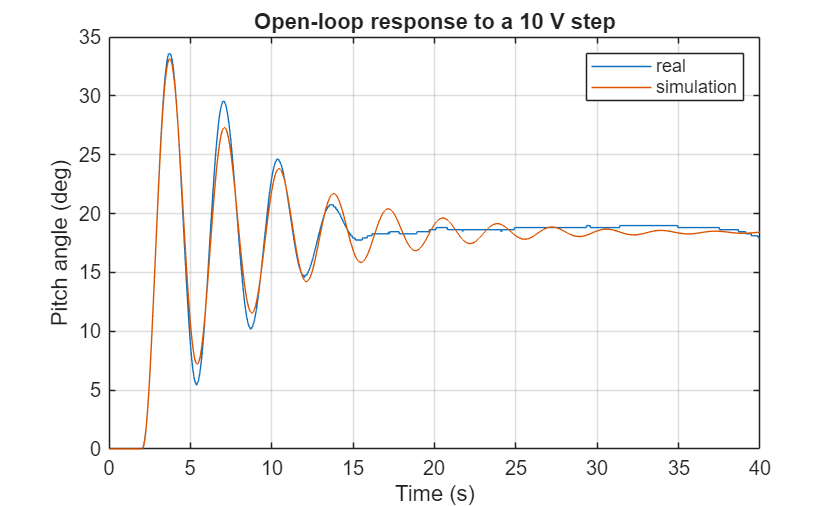

k4 = 8e-7;
Dp = 0.0065;
sim('HalfQuadOL.slx'); % Run the SImulink in Simulation mode

plot(theta_r_saved.time,theta_r_saved.signals.values,theta.time,theta.signals.values);legend('real','simulation')
title('Open-loop response to a 10 V step');
xlabel('Time (s)');
ylabel('Pitch angle (deg)');
grid on;

Iterate this section until you have a good fit between the Simulated model and the real one

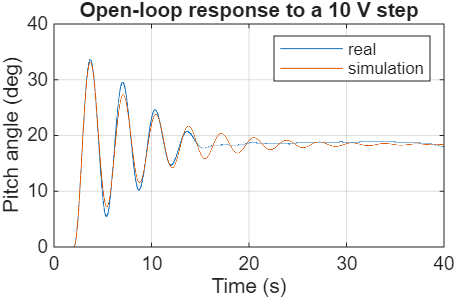

#### **We adjusted k4 and Dp manually to match the simulated and measured responses. We compared the peak angle, the timing and decay of the oscillations, the final angle and the approximate settling time. We also calculated the RMSE using samples at matching times after the voltage step. A smaller RMSE indicates a closer overall match.**

#### 
$$\varepsilon_i=\theta_{\mathrm{sim}}(t_i)-\theta_{\mathrm{real}}(t_i),
\qquad
\mathrm{RMSE}=\sqrt{\frac{1}{n}\sum_{i=1}^{n}\varepsilon_i^2}$$


#### **Here, n is the number of samples used in the comparison. When both angles are expressed in degrees, the error and RMSE are also in degrees.**

use = theta.time >= 2; %the step input at t = 2
RMSE = sqrt(mean((theta.signals.values(use)-theta_r_saved.signals.values(use)).^2))

RMSE = 0.8396

#### **The RMSE is 0.8396 deg, which is below 1 deg. This indicates a reasonable overall agreement between the simulated and measured angles.**

## 2 : Model linearization

**Do not modify this section, it is just used to create linear model from the non-linear simulation model.**

We first extract a linear model from the full non linear model.

x0=[];
u0=0;%Input is initialized at 0V
y0=[]; 
ix=[];
iu=1; %Input 1 is freezed
iy=[];
[xtrim,utrim,ytrim,dxtrim] = trim('ControlMec',x0,u0,y0,ix,iu,iy);
[Amec,Bmec,Cmec,Dmec] = linmod('ControlMec', xtrim, utrim);
Gmec=ss(Amec,Bmec,Cmec,Dmec);

This system has two outputs. We can extract the linear model F from u to theta (angle):

F = Gmec(1,1); % Model from u to theta

We transform F  (state space models) into transfer function

F = tf(F);

We compute the minimal realization (pole-zero compensation)

tol = 1e-6; %tolerance for pole-zero compenssation (default is 1e-8)
F = minreal(F,tol);

F (transfer function from u to the angle theta ) will be used for the design of the controller (next sections).

## 3. Is it possible to control the angle with just a proportional controller ?

We want to explore the possibility of designing a simple proportional controler. The control law will be:


$$u=k_p \times \;\left({\textrm{theta}}_{\textrm{ref}} -\textrm{theta}\right)$$


**Question 1 : Compute the poles of the open loop system. (Functions pole, zero, damp)**

TEXT.

%code
pole(F)

ans = 1.0e+03 *

  -7.2226 + 0.0000i
  -0.0200 + 0.0000i
  -0.0002 + 0.0019i
  -0.0002 - 0.0019i


zero(F)


ans =

  0×1 empty double column vector



damp(F)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.51e-01 + 1.92e+00i     7.83e-02       1.93e+00         6.62e+00    
 -1.51e-01 - 1.92e+00i     7.83e-02       1.93e+00         6.62e+00    
 -2.00e+01                 1.00e+00       2.00e+01         5.00e-02    
 -7.22e+03                 1.00e+00       7.22e+03         1.38e-04    


Is the open loop system well damped?

#### **Ans: All 4 poles lie in the left-half plane (LHP), so the open-loop system is stable. The poles are approximately -0.151+j1.924, -0.151-j1.924, -20.0 and -7223 [s^-1]. However, the dominant poles, approximately -0.151 +- j1.924, have a small damping ratio of about 0.078. Therefore, the system is poorly damped and its oscillations decay slowly. The other 2 poles are much faster and have less influence on the main transient response. The command zero(F) returns an empty array, meaning that the model has no finite zeros.**

**Question 2 : what is value of kp that makes the closed loop system unstable?**

TEXT.

%code
% Gm gives the proportional gain limit
[Gm,Pm,Wcg,Wcp] = margin(F)

Gm = 0.9139

Pm = -0.7822

Wcg = 3.1238

Wcp = 3.2142

Gm_dB = 20*log10(Gm)

Gm_dB = -0.7820

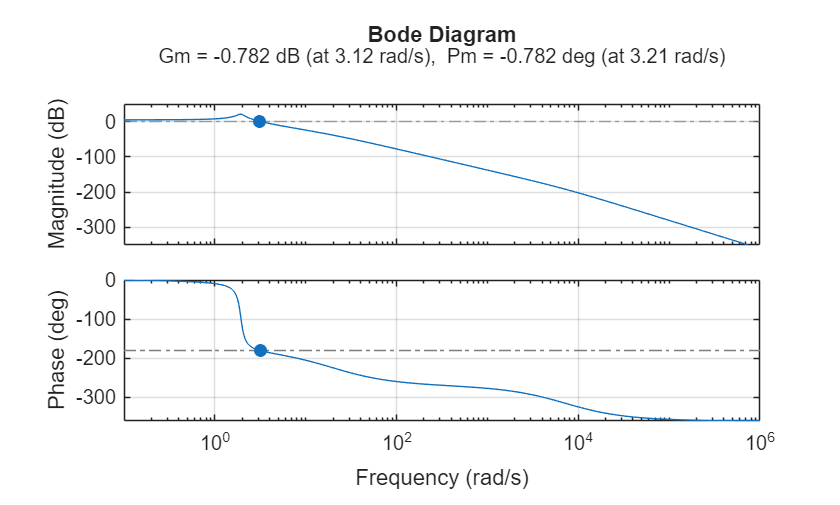

margin(F); grid on;

kp = 0.92; %Above the critical gain:unstable closed loop
cl = feedback(kp*F,1)


cl =
 
                        8.991e05
  -----------------------------------------------------
  s^4 + 7243 s^3 + 1.467e05 s^2 + 7.068e04 s + 1.438e06
 
Continuous-time transfer function.


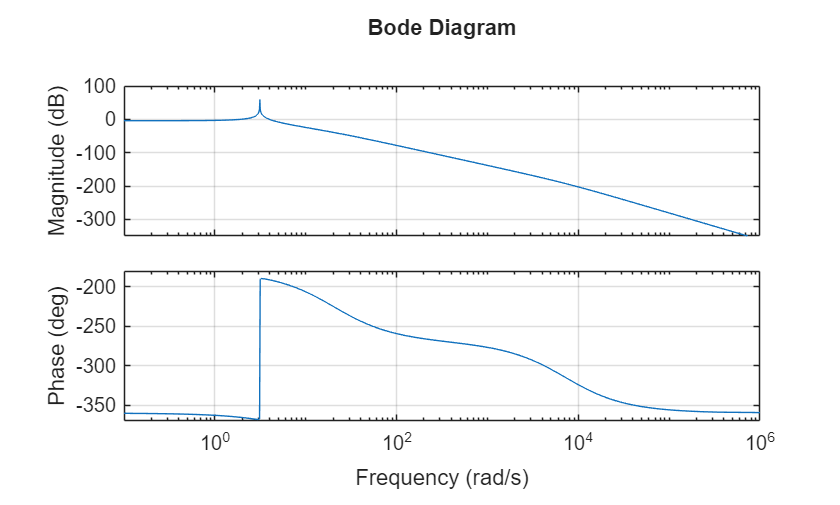

figure; bode(cl); grid on;

pole(cl) %Check for RHP poles

ans = 1.0e+03 *

  -7.2226 + 0.0000i
  -0.0203 + 0.0000i
   0.0000 + 0.0031i
   0.0000 - 0.0031i


#### **Ans: The gain margin is Gm = 0.9139, which gives the critical proportional gain. At kp about 0.9139 V/deg, the closed-loop system is marginally stable. Increasing kp above this value makes it unstable. Therefore, for stable proportional control, we require 0 < kp < 0.9139.**

**Question 3 : Is it possible to achieve a closed bandwidth that fits the requirement?**

TEXT.

%code
kp2 = 0.5

kp2 = 0.5000

cl2 = feedback(kp2*F,1)


cl2 =
 
                        4.886e05
  -----------------------------------------------------
  s^4 + 7243 s^3 + 1.467e05 s^2 + 7.068e04 s + 1.027e06
 
Continuous-time transfer function.


bandwidth(cl2)

ans = 4.0973

[Gm2,Pm2,Wcg2,Wcp2] = margin(kp2*F)

Gm2 = 1.8278

Pm2 = 6.2437

Wcg2 = 3.1238

Wcp2 = 2.6421

#### Ans: Yes. With kp = 0.5, the closed-loop bandwidth is approximately 4.0973 rad/s, which satisfies the required bandwidth range. However, the phase margin is only about 6.24 deg, so the response is poorly damped.

## 4. Design of phase lead controller

We first focus on the first two requirements: closed loop bandwidth in the range 3.5 to 4.5 rad/s, phase margin in the range 45 to 55 degrees

**Question 4: Design a PD controller that allows to reach the requirement**

You will prove the requirement by Bode diagram analysis, step response in simulation

TEXT.

kp = 0.2;
wd = 3.3;
PD = kp*(1 + s/wd); %

lead = feedback(PD*F,1)


lead =
 
                      1.955e05 s + 6.45e05
  ------------------------------------------------------------
  3.3 s^4 + 2.39e04 s^3 + 4.842e05 s^2 + 4.287e05 s + 2.422e06
 
Continuous-time transfer function.


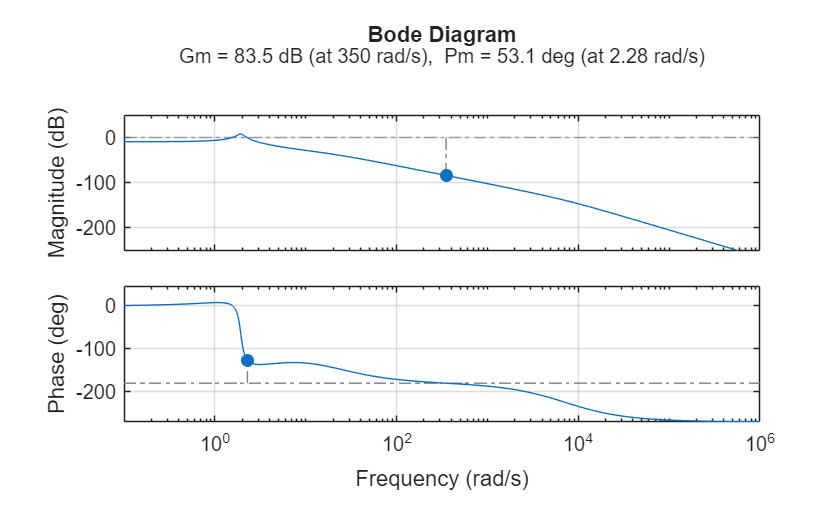

margin(PD*F); grid on;

[GmL,PmL,WcgL,WcpL] = margin(PD*F)

GmL = 1.5017e+04

PmL = 53.1039

WcgL = 350.4452

WcpL = 2.2820

bandwidth(lead)

ans = 4.0158

pole(lead)

ans = 1.0e+03 *

  -7.2226 + 0.0000i
  -0.0197 + 0.0000i
  -0.0003 + 0.0022i
  -0.0003 - 0.0022i


zero(lead)

ans = -3.3000

#### **Ans:** Proportional control alone does not satisfy both requirements. Increasing kp raises the bandwidth, but for this plant it also reduces the phase margin and makes the response more oscillatory. We therefore add derivative action to provide phase lead and improve damping.


$$C_{PD}(s)=k_p\left(1+\frac{s}{\omega_d}\right)
=0.2\left(1+\frac{s}{3.3}\right)$$


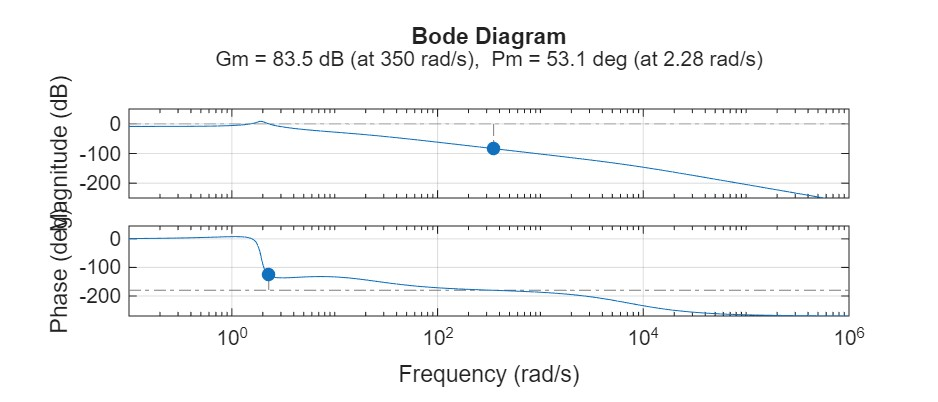

#### We adjusted kp and wd and checked the Bode diagram and step response after each change. The selected values are kp = 0.2 and wd = 3.3. The zero at -3.3 adds phase lead and improves the phase margin. The loop phase margin is approximately 53.10 deg, and the closed-loop bandwidth is approximately 4.016 rad/s. Both values satisfy the required ranges.

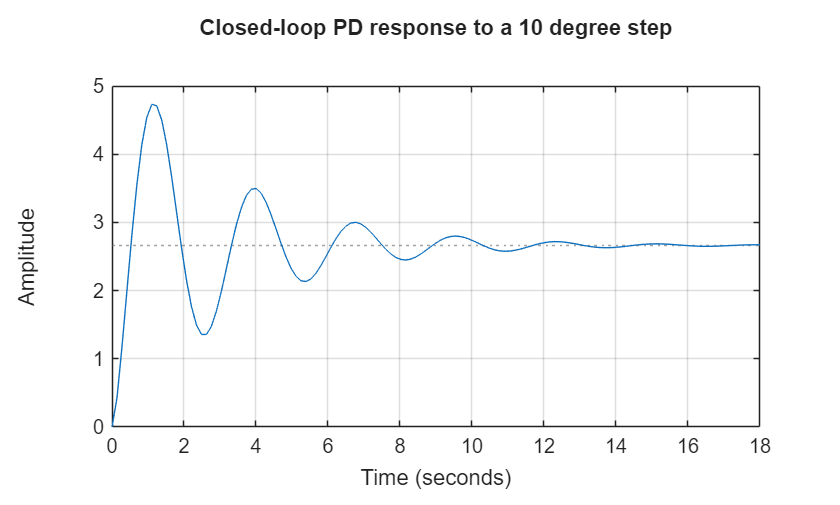

figure;
step(10*lead); %10deg
grid on;
title('Closed-loop PD response to a 10 degree step');

stepinfo(lead)

ans = struct with fields:
         RiseTime: 0.3954
    TransientTime: 12.4374
     SettlingTime: 12.4374
      SettlingMin: 0.1357
      SettlingMax: 0.4731
        Overshoot: 77.6326
       Undershoot: 0
             Peak: 0.4731
         PeakTime: 1.1055


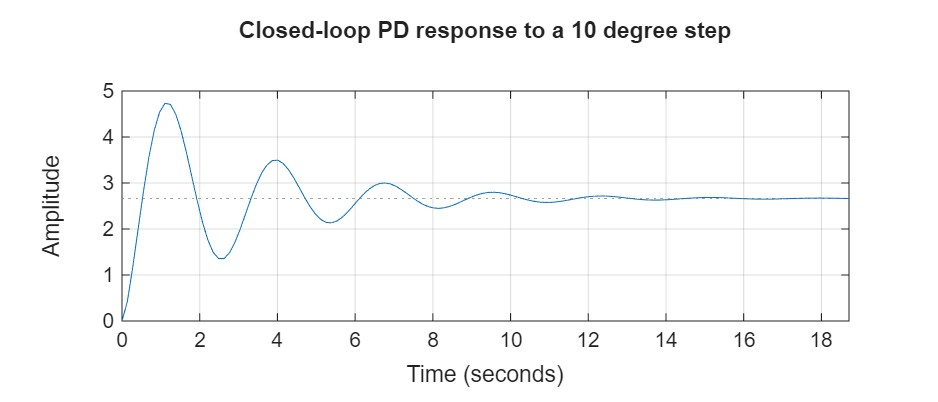

#### The step response (Simulation) is stable but still oscillatory, and it settles below the reference because PD control leaves a static error. Integral action is added later to remove this error.

**Question 5: compare the step response of the simulation and the step response of the real system**

The PD you have designed being non causal (more zeros than poles) it cannot be inserted directly into the Simulink. You can proceed in several ways to insert your PD controller into the Simulink:

Solution 1: Replace your PD (non causal) to a filtered PD  (causal):

N = 10;
PDfilt = kp*(1 + s/wd)/(1 + s/wd/N);

Insert into the SImulink with an LTI block:

 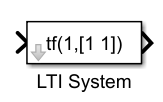

Solution 2: code the derivation of the error based on the PD  equations:


$$u(s) = k_p \times \left(1 + \frac{s}{\omega_d}\right) \,\, \epsilon(s)\\
u(t) = k_p\times\left(\epsilon(t) + \frac{1}{\omega_d}\dot{\epsilon}(t)\right)$$


$\dot{\epsilon}(t)$ will be generated by a derivative block:

Whatever solution you choose you wil discuss the choice of the filtering term (N in Solution 1 and c in Solution 2)

TEXT.

%code
lead2 = feedback(PDfilt*F,1)


lead2 =
 
                              6.45e06 s + 2.128e07
  ----------------------------------------------------------------------------
  3.3 s^5 + 2.401e04 s^4 + 1.273e06 s^3 + 1.621e07 s^2 + 1.592e07 s + 7.992e07
 
Continuous-time transfer function.


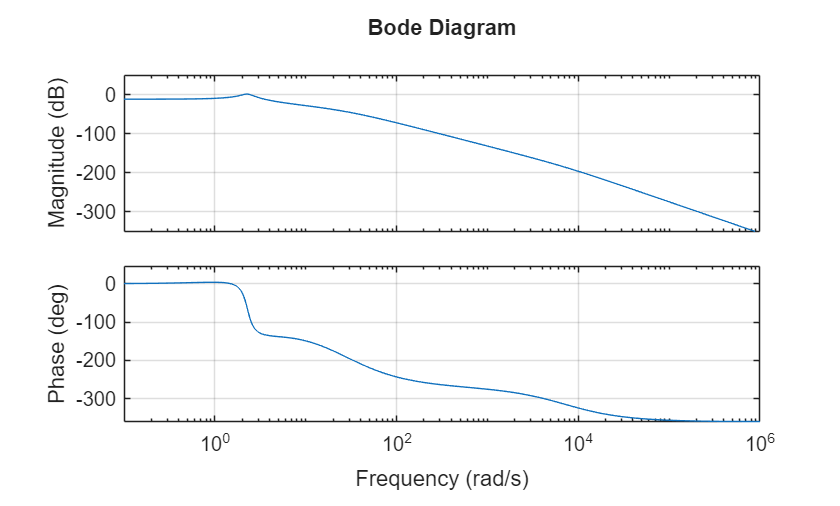

figure; bode(lead2); grid on;

[GmL2,PmL2,WcgL2,WcpL2] = margin(PDfilt*F)

GmL2 = 96.7077

PmL2 = 49.1971

WcgL2 = 22.3184

WcpL2 = 2.2810

bandwidth(lead2)

ans = 4.0313

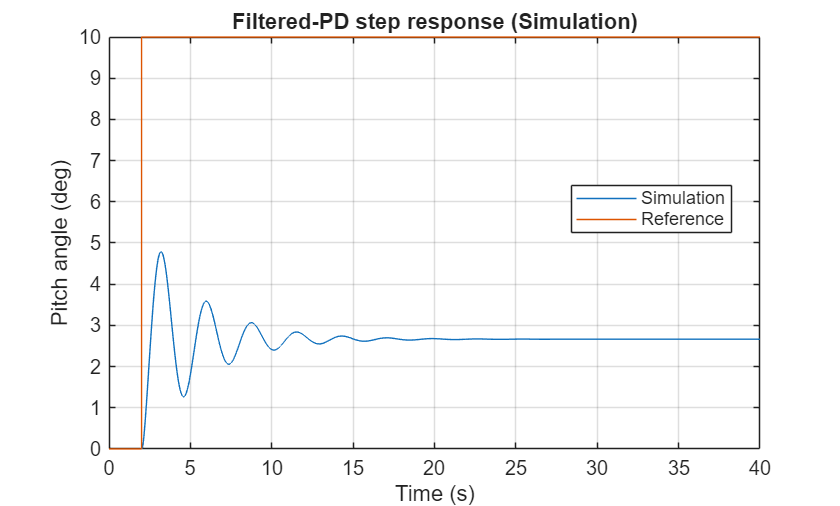

C = PDfilt;
sim('HalfQuadCL.slx');
load('data_closed_loop.mat');

t = step_r_integral_saved.time;
r = step_r_integral_saved.signals.values;
theta_real = r - error_r_derivative_saved.signals.values;

figure;
plot(theta.time,theta.signals.values,t,r);
legend('Simulation','Reference','Location','best');
title('Filtered-PD step response (Simulation)');
xlabel('Time (s)');
ylabel('Pitch angle (deg)');
grid on;

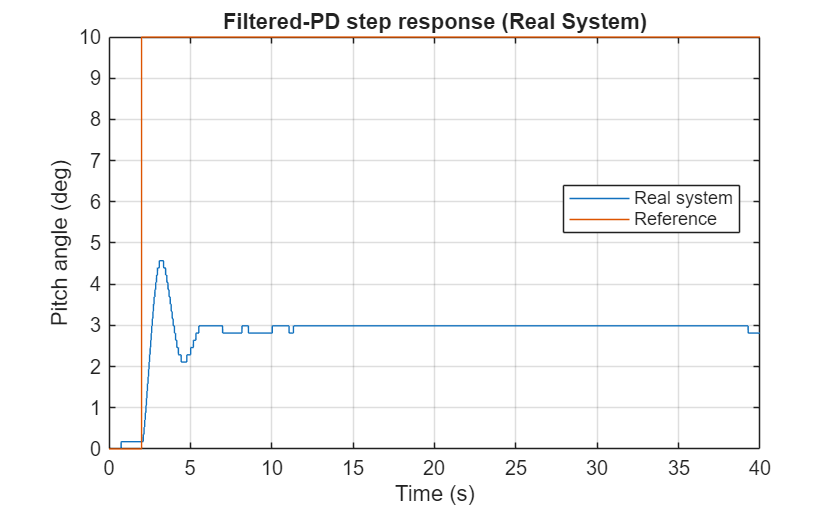

figure;
plot(t,theta_real,t,r);
legend('Real system','Reference','Location','best');
title('Filtered-PD step response (Real System)');
xlabel('Time (s)');
ylabel('Pitch angle (deg)');
grid on;

#### **Ans:** We chose Solution 1 and implemented a filtered PD controller using an LTI System block:

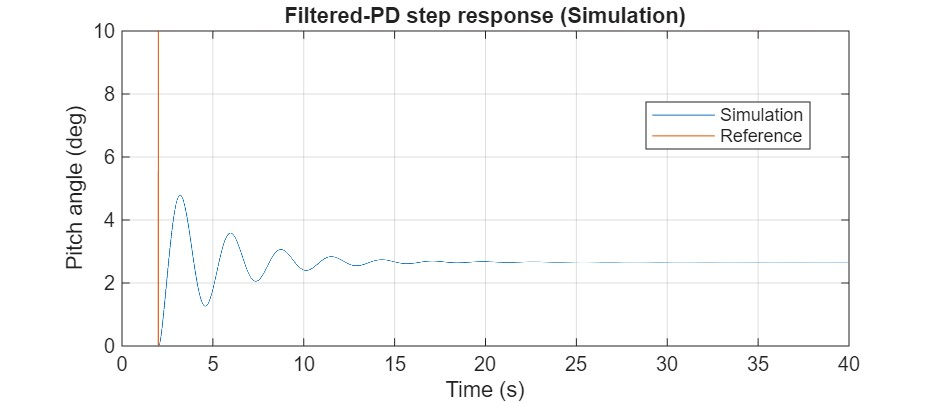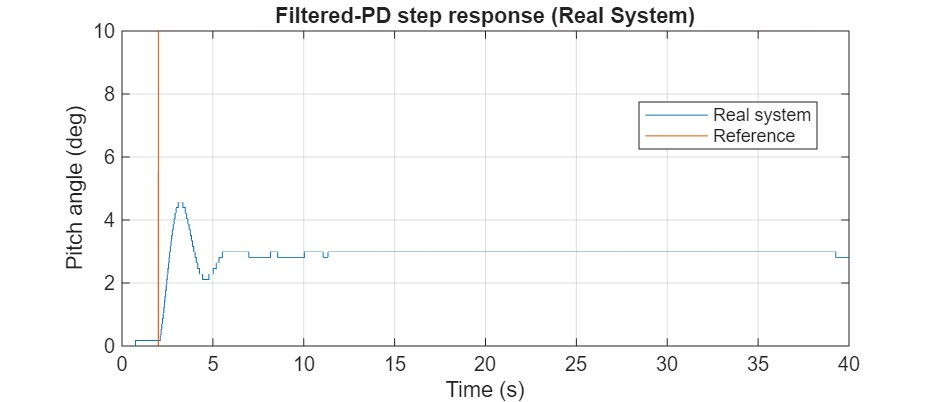

#### We selected N = 10, placing the filter pole at 33 rad/s (first-order low-pass filter), above the zero at 3.3 rad/s. This limits high-frequency noise amplification while retaining enough phase lead to satisfy the requirements.

#### 
$$C_{\mathrm{PD,f}}(s)=k_p\frac{1+s/\omega_d}{1+s/(N\omega_d)}=0.2\frac{1+s/3.3}{1+s/33}$$


#### The loop phase margin is approximately 49.20 deg, and the closed-loop bandwidth is 4.03 rad/s. Both satisfy the requirements. For the same 10 deg reference step, the simulated and measured responses both settle below the reference, showing that PD control leaves a static error.

**Question 6: Compare the expected static error based on the LTI models and the one measured on the real system**

TEXT.

%code
expected_error = 10/(1 + dcgain(PDfilt*F))

expected_error = 7.3367

load('data_closed_loop.mat','error_r_derivative_saved');
t = error_r_derivative_saved.time;
use = t >= t(end)-5;
measured_error = mean(error_r_derivative_saved.signals.values(use))

measured_error = 7.0374

#### **Ans:** The LTI model predicts a static error of approximately 7.34 deg. The average measured error over the final 5 seconds (when the response is approximately at steady state) is 7.04 deg. These values are close, and both show that PD control leaves a large static error. Integral action is therefore needed to remove this error.

## 5. Design of Integral action

In order to cancel the static error we now insert an integral action into our controller. Tune the integral action in order to cancel the static error in a reasonnable time. Discuss the tuning.

**Question 7: Discuss the tuning of the controller**

TEXT.

kp = 0.4;
wd = 1.3;
N = 30;
wi = 1.5;

PDfilt = kp*(1 + s/wd)/(1 + s/(N*wd));
I = 1 + wi/s;
C = PDfilt*I;
sim('HalfQuadCL.slx');
integral = feedback(C*F,1);

[GmLI,PmLI,WcgLI,WcpLI] = margin(C*F)

GmLI = 22.7218

PmLI = 38.2383

WcgLI = 25.0502

WcpLI = 3.4439

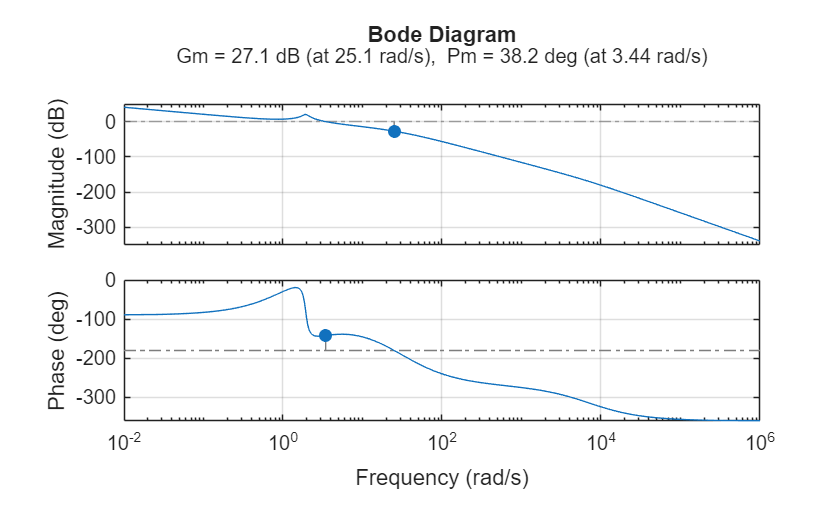

figure; margin(C*F); grid on;

bandwidth(integral)

ans = 5.0365

dcgain(integral)

ans = 1

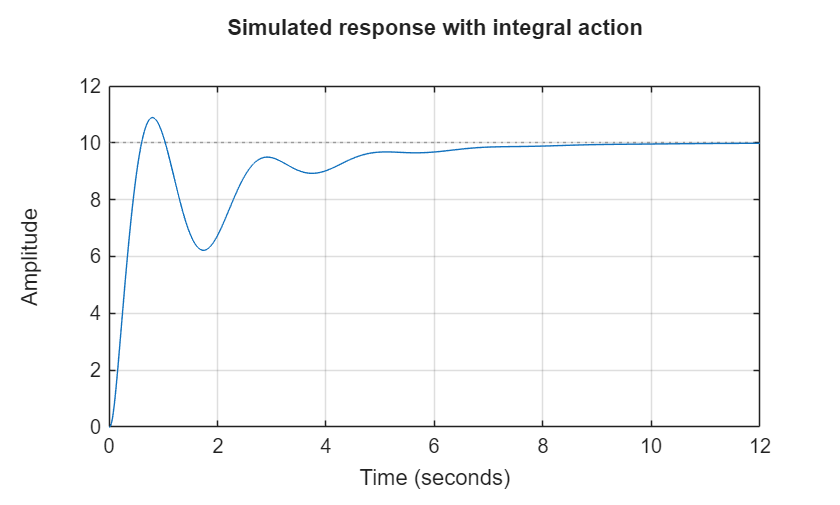

figure; step(10*integral); grid on;
title('Simulated response with integral action');

stepinfo(integral)

ans = struct with fields:
         RiseTime: 0.4032
    TransientTime: 6.5997
     SettlingTime: 6.5997
      SettlingMin: 0.6217
      SettlingMax: 1.0888
        Overshoot: 8.8824
       Undershoot: 0
             Peak: 1.0888
         PeakTime: 0.8015


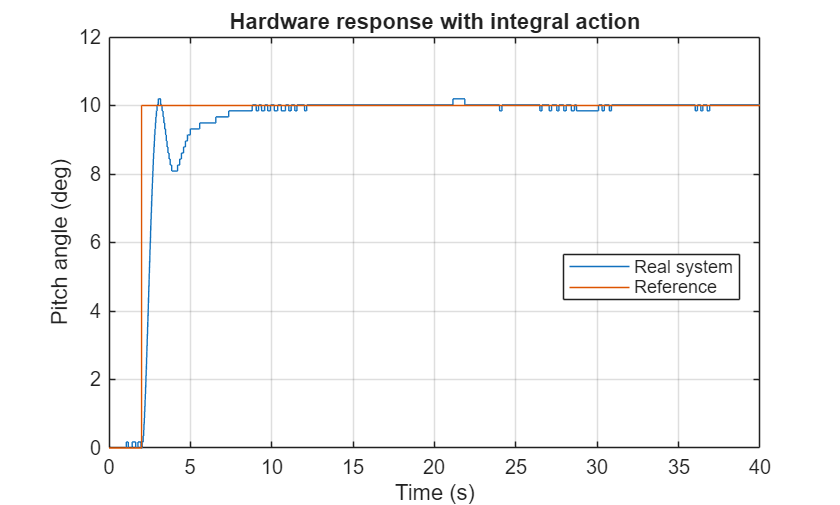

load('data_closed_loop.mat');

figure;
plot(theta_r_integral_saved.time,theta_r_integral_saved.signals.values, step_r_integral_saved.time,step_r_integral_saved.signals.values);
legend('Real system','Reference','Location','best');
title('Hardware response with integral action');
xlabel('Time (s)');
ylabel('Pitch angle (deg)');
grid on;

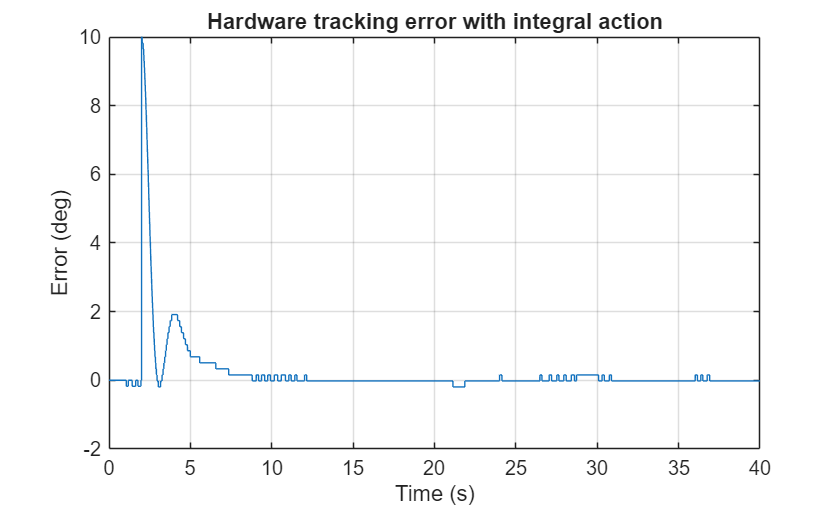

figure;
plot(error_r_integral_saved.time,error_r_integral_saved.signals.values);
title('Hardware tracking error with integral action');
xlabel('Time (s)');
ylabel('Error (deg)');
grid on;

#### **Ans:** We added integral action to remove the static error. Since it changes the loop gain and phase, we retuned kp, wd, N and wi to satisfy the final bandwidth and phase margin requirements. The phase margin is approximately 38.24 deg, and the closed-loop bandwidth is 5.04 rad/s.


$$C_{\mathrm{PD,f+PI}}(s)=k_p\frac{1+s/\omega_d}{1+s/(N\omega_d)}\left(1+\frac{\omega_i}{s}\right)=0.4\frac{1+s/1.3}{1+s/39}\left(1+\frac{1.5}{s}\right)$$


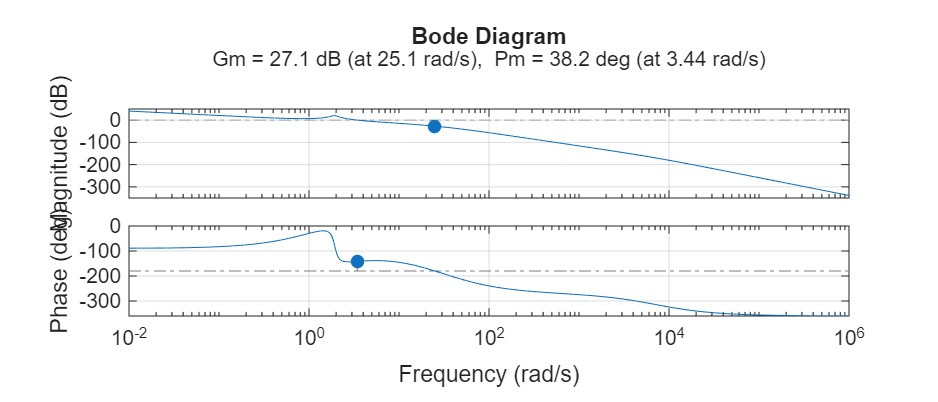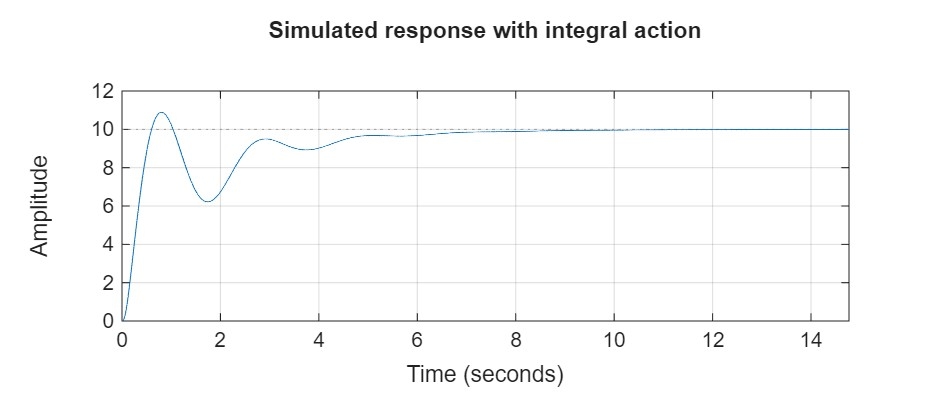

#### The simulated response has a rise time of approximately 0.40 s, a settling time of 6.60 s and an overshoot of 8.88%. The closed-loop DC gain is 1, so the model predicts zero static error.

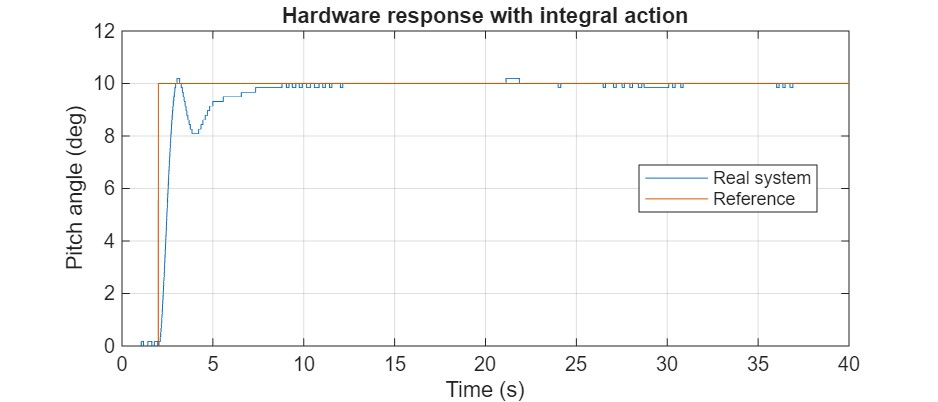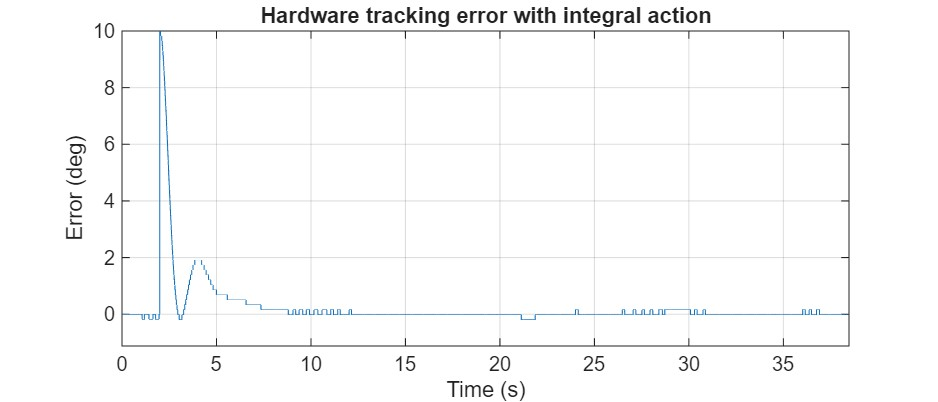

#### From the hardware plots, the angle reaches the 10 deg reference with a small overshoot and settles close to the reference. The tracking error remains close to zero after the transient, showing that integral action removes the static error.